# Report

by: ardimas (ardimasandipurwita@outlook.com)

20 Aug 2019

clear
addpath('./../../lib/filter')
addpath('./../../lib/misc')
addpath('./../../lib/simulator')
addpath('./../../lib/tgbb')
addpath('./../../data/freqresponse')

## Validation

In the previous report, I compared my own simulation setup and that of Tamas. There is a 5 dB difference. I suspected that such gain comes from the fact that Tamas used different AFE that has 3dB difference in passband gain as following.

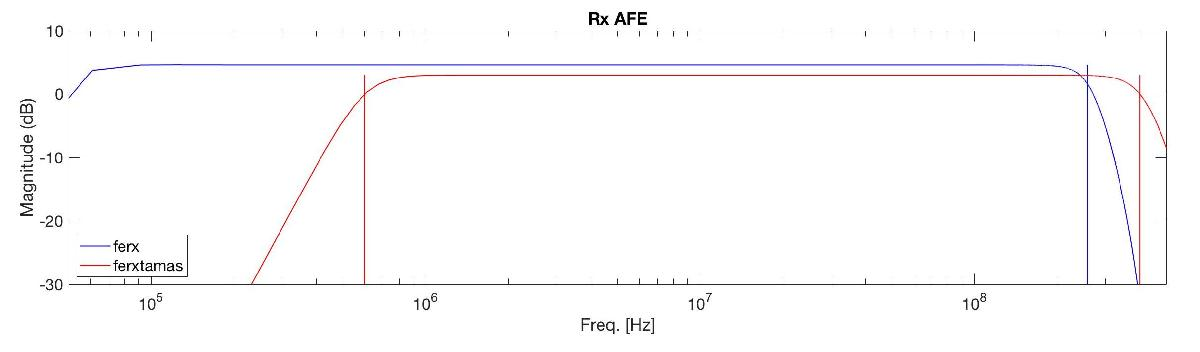

I'm just quickly running my simulation for the 'S1_D1' configuration with the same setup as before, but I only changed the AFEs following Tamas' configuration. The result is as follows.

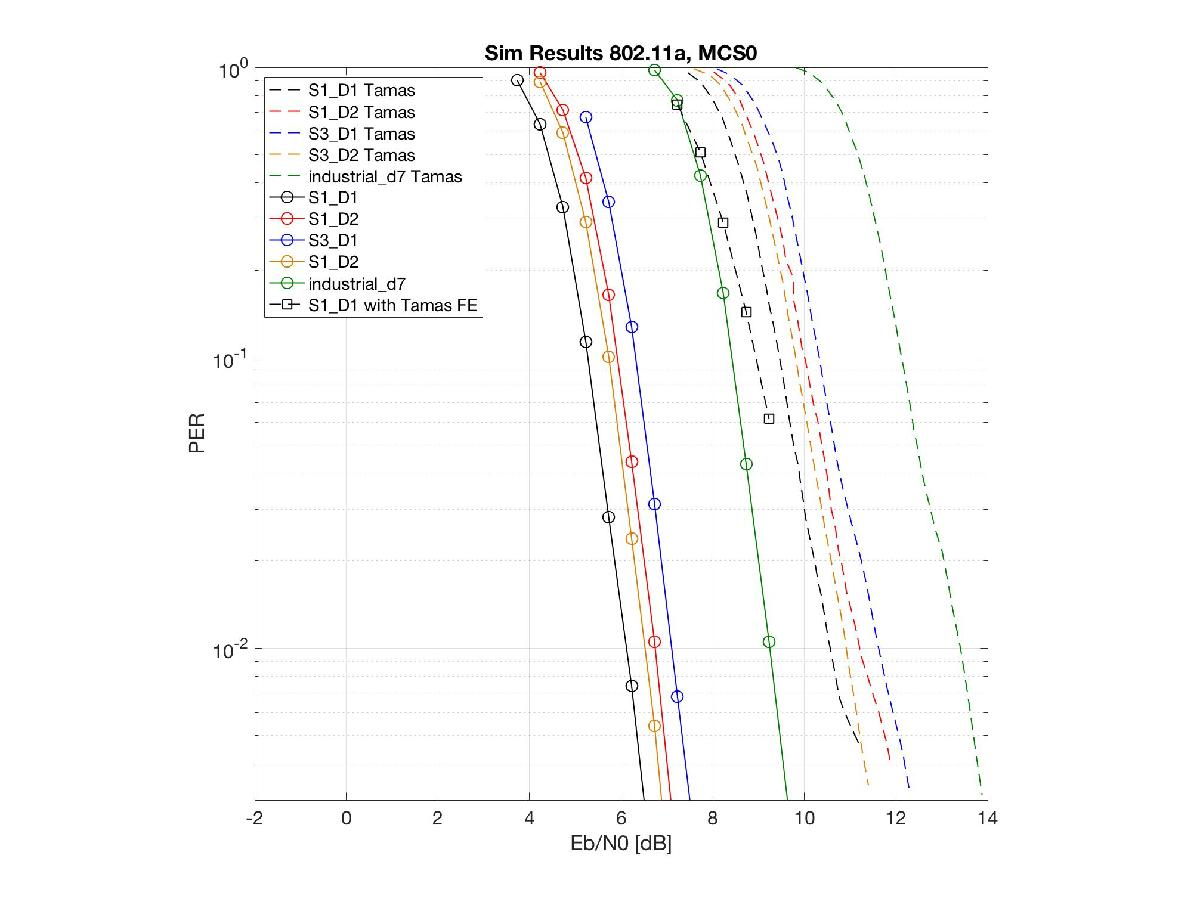

Comparing betwen the black straight line with the circle markers and the black dashed line with the square markers, we can see the 4dB difference. There's still difference with Tamas' result (see the black dashed curve without marker). The reason is that there are still other minor differences such as, the use of windowed OFDM waveform and pulse shaping and matched filter implementations.

## Simulations based on transmit optical power

On the Aug 20's meeting, Stefan proposed to run simulations based on a transmit optical power while fixing the noise variance. 

The changes that I made are that:

- replace the signal dependent shot noise with a white Gaussian noise and

- the power of the output of DC bias and clipping is adjusted according to the evaluated transmit optical power value.

The noise floor (NF) value is taken from [https://mentor.ieee.org/802.11/dcn/18/11-18-1423-08-00bb-tgbb-simulation-scenarios.docx](https://mentor.ieee.org/802.11/dcn/18/11-18-1423-08-00bb-tgbb-simulation-scenarios.docx), which says that the NF is -70dBm.

I will only run the simulations with two extreme scenarios, i.e., 'S1_D1' and 'industrial_d7'. Let's see their frequency responses as follows.

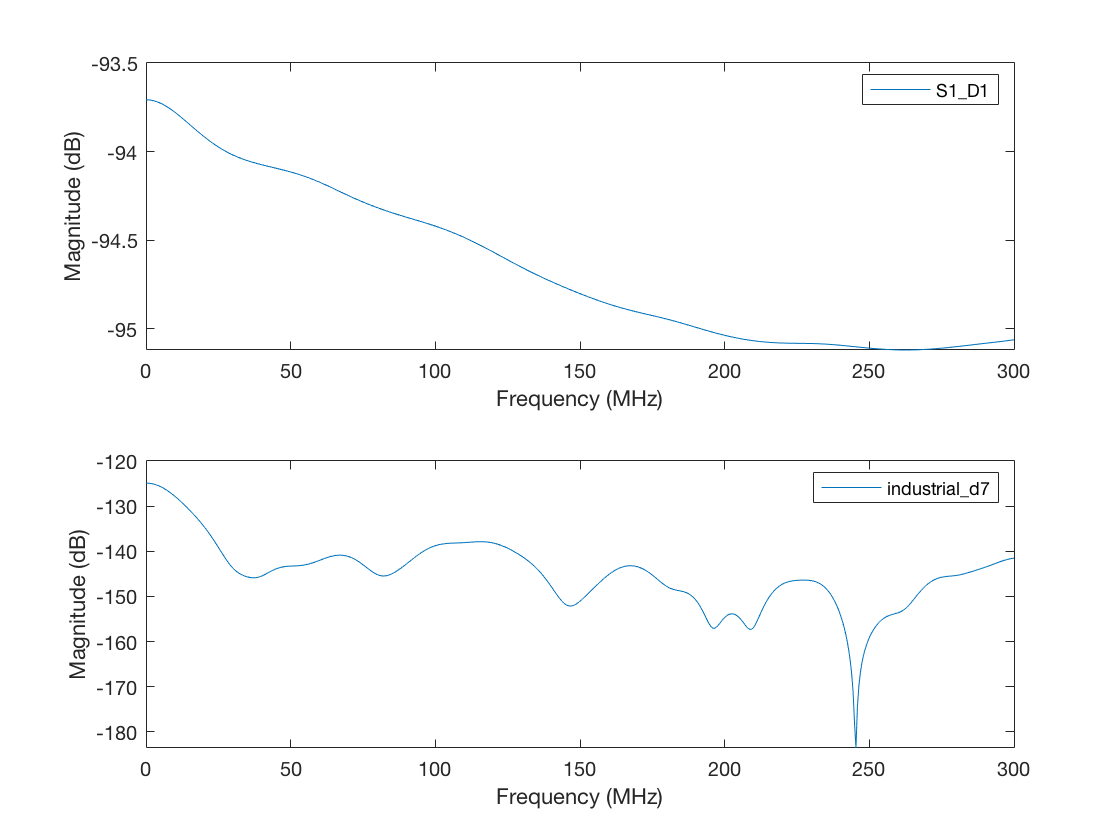

fs = 1e9; % sampling freq.

load('S1_D1.mat')
[H_S1D1,f_S1D1] = freqz(averun2,1,2001,'whole',fs);
load('industrial_d7.mat')
[H_industry,f_industry] = freqz(averun2,1,2001,'whole',fs);

figure
subplot(2,1,1)
plot(f_S1D1/1e6,pow2db(abs(H_S1D1).^2),'DisplayName','S1\_D1');
ylabel('Magnitude (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
legend -DynamicLegend
subplot(2,1,2)
plot(f_industry/1e6,pow2db(abs(H_industry).^2),'DisplayName','industrial\_d7');
ylabel('Magnitude (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
legend -DynamicLegend

Let's now convert the previous SNR results (see folder ./../initial_result_payload_tgbb11a) to the transmit optical power for sanity check.

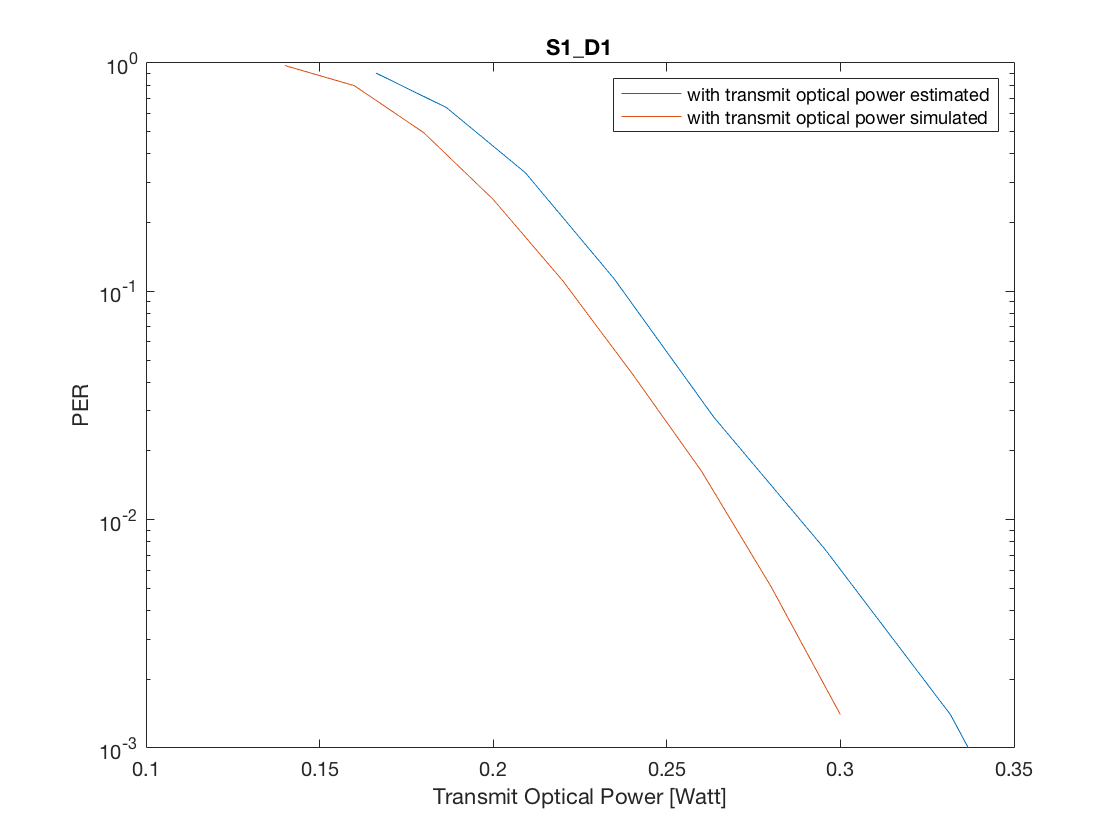

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D1_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H_S1D1).^2);

figure
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','with transmit optical power estimated')
hold on

load PERvsSNR_NHT_Power_S1D1.mat
semilogy(ptx,packetErrorRate,'DisplayName','with transmit optical power simulated')

xlabel('Transmit Optical Power [Watt]')
ylabel('PER')
title('S1\_D1')
ylim([1e-3,1])
legend -DynamicLegend

For 'S1_D1', we need 300 mW to achieve PER of 1e-3. The difference between the estimated and simulated ones is due to the exclusion of the signal-dependent shot noise in the simulation based on the transmit optical power. In my opinion, this estimation is good enough for quick analysis.

Let's do another sanity check with the 'industrial_d7' in order to be more confident with the estimation method.

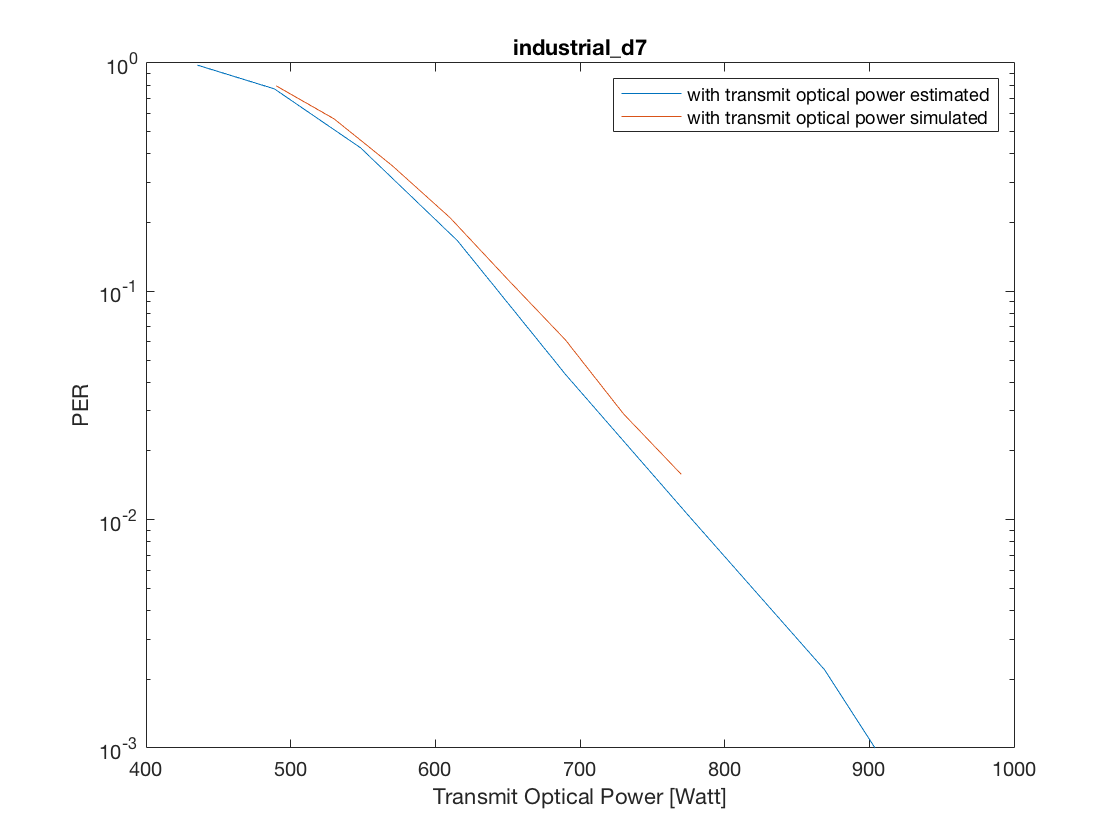

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_industriald7_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H_industry).^2);

figure
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','with transmit optical power estimated')
hold on

load PERvsSNR_NHT_Power_industriald7.mat
semilogy(ptx,packetErrorRate,'DisplayName','with transmit optical power simulated')

xlabel('Transmit Optical Power [Watt]')
ylabel('PER')
title('industrial\_d7')
ylim([1e-3,1])
legend -DynamicLegend

Now, let's convert them for all 5 configurations.

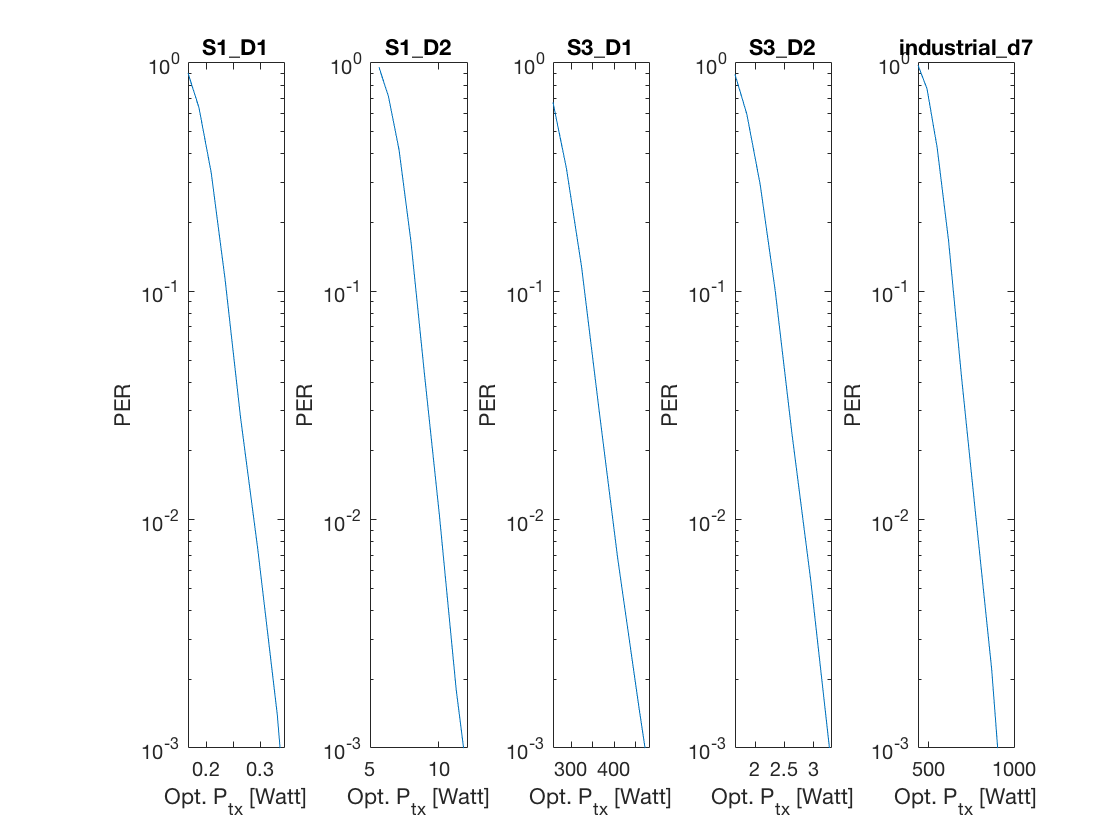

load('S1_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D1_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H).^2);

figure
subplot(1,5,1)
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','S1\_D1')
xlabel('Opt. P_{tx} [Watt]')
ylabel('PER')
title('S1\_D1')
ylim([1e-3,1])
% legend -DynamicLegend


load('S1_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D2_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H).^2);

subplot(1,5,2)
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','S1\_D2')
xlabel('Opt. P_{tx} [Watt]')
ylabel('PER')
title('S1\_D2')
ylim([1e-3,1])
% legend -DynamicLegend

load('S3_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S3D1_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H).^2);

subplot(1,5,3)
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','S3\_D1')
xlabel('Opt. P_{tx} [Watt]')
ylabel('PER')
title('S3\_D1')
ylim([1e-3,1])
% legend -DynamicLegend

load('S3_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S3D2_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H).^2);

subplot(1,5,4)
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','S3\_D2')
xlabel('Opt. P_{tx} [Watt]')
ylabel('PER')
title('S3\_D2')
ylim([1e-3,1])
% legend -DynamicLegend

load('industrial_d7.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);

load ./../initial_result_payload_tgbb11a/PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_industriald7_beta01.mat

snrLinear = db2pow(snr);
NF = db2pow(-70-30); % NF is -70dBm
SAfterCIR = snrLinear*NF;
requiredOpticalPowEstimated = SAfterCIR/max(abs(H).^2);

subplot(1,5,5)
semilogy(requiredOpticalPowEstimated,packetErrorRate,'DisplayName','industrial\_d7')
xlabel('Opt. P_{tx} [Watt]')
ylabel('PER')
title('industrial\_d7')
ylim([1e-3,1])

% legend -DynamicLegend

Based on the above results, the feasible configurations are 'S1_D1', 'S1_D2' and 'S3_D1'. The configurations that do not make sense are 'S3_D1' and 'industrial_d7'. The question is now whether we can infer it from the frequency reponses only. Let's see them once more.

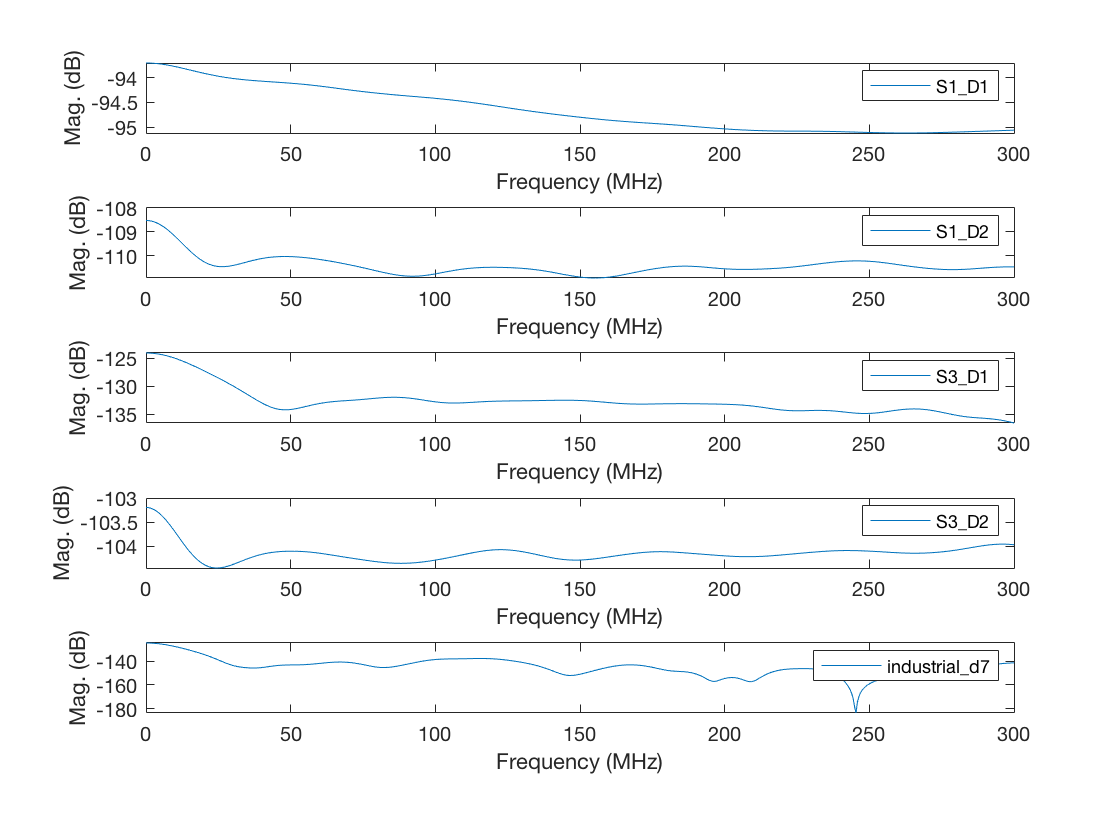

fs = 1e9;
figure
subplot(5,1,1)
load('S1_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S1\_D1');
legend -DynamicLegend
ylabel('Mag. (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
subplot(5,1,2)
load('S1_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S1\_D2');
legend -DynamicLegend
ylabel('Mag. (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
subplot(5,1,3)
load('S3_D1.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S3\_D1');
legend -DynamicLegend
ylabel('Mag. (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
subplot(5,1,4)
load('S3_D2.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','S3\_D2');
legend -DynamicLegend
ylabel('Mag. (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])
subplot(5,1,5)
load('industrial_d7.mat')
[H,f] = freqz(averun2,1,2001,'whole',fs);
plot(f/1e6,pow2db(abs(H).^2),'DisplayName','industrial\_d7');
legend -DynamicLegend
ylabel('Mag. (dB)')
xlabel('Frequency (MHz)')
xlim([0,300])

I think we can predict whether a configuration is feasible for light communications if the DC gain is greter than -109 dB. And, it is not feasible if the DC gain is below -125 dB. 

## Remarks

This type of estimation can be used to check the feasibility of a configuration given its freq. response only. 

In order to gain more accurate the feasible and infeasible ranges we need to run more simulations with different freq. responses having different DC gain.